# Model Refrence Adaptive control of autonomous vehicle

In this project, the goal is to design a controller for an autonomous vehicle with an unknown system model. Since the system model is not known, using **Model Reference Adaptive Control (MRAC)** is suggested to make the controlled system follow a desired reference model. The vehicle is modeled in Simulink, and the MRAC controller is implemented using the **Model Reference Adaptive Control block** provided by the **Simulink Control Design** toolbox.

## Control System

Due to uncertainties in the system dynamics and changes in weather conditions, the vehicle experiences undesired oscillations in its velocity and roll. The goal of the MRAC controller is to eliminate these unwanted oscillations. A baseline controller can then be designed to achieve the desired reference behavior.

The following nonlinear uncertain dynamic model is proposed for the motions of an autonomous ground vehicle:

**Longitudinal Dynamics**:


$$u˙=w0+w1u+w2u\left|u\right|-kfu\left|u\right|+B1\left(x\right)a+d\textrm{long}\left(x\right)$$


Where:

- kfu∣u∣: nonlinear rolling resistance / aerodynamic drag

- dlong(x)=−gsin (θ): road slope disturbance

- B1(x): throttle/brake effectiveness (sign known)

**Lateral Dynamics**:


$$v˙=w3+w4y+w5v+w6y\left|y\right|+w7v\left|v\right|+B2\left(x\right)\delta +d\textrm{lat}\left(x\right)$$


Where:

- dlat(x): lateral disturbances (e.g. wind, curved road)

- B2(x): steering effectiveness (sign known)

The goal is for the vehicle’s lateral displacement and velocity to follow the behavior of the following second-order reference model***:***

***Reference Model for Longitudinal Velocity***:$¨y_m +4˙y_m +4y_m =4r\left(t\right)$

 ***Reference Model for Lateral Displacement***:$¨y_m +4˙y_m +4y_m =4r_y \left(t\right)$

## Define Nominal and Reference Models 

Specify the following simplified second-order nominal model for the roll dynamics:

% Lateral dynamics nominal model (second integrator)
A_lat = [0 1; 0 0];  % Nominal A matrix for lateral motion
B_lat = [0; 1];      % Nominal input is steering angle delta
C=[1 0];
D=0;

% Longitudinal dynamics nominal model (second integrator)
A_long = [0 1; 0 0]; % Nominal A matrix for longitudinal motion
B_long = [0; 1];     % Nominal input is acceleration a


Define the reference model as the stable second-order system defined previously. The controller adapts its uncertainty model to achieve the same second-order behavior as this model:

% Reference model for lateral motion (stable 2nd-order system)
Am_lat = [0 1; -4 -4];  % desired dynamics for lateral displacement
Bm_lat = [0; 4];

% Reference model for longitudinal velocity (stable 2nd-order system)
Am_long = [0 1; -2 -2]; % desired dynamics for speed tracking
Bm_long = [0; 2];

Specify the initial conditions for the nominal and reference models:

% Initial lateral velocity and displacement
v0 = 0;
y0 = 0;
% Initial longitudinal velocity
u0 = 0;
% State vectors for lateral and longitudinal motion
x_lat = [y0; v0];    % [lateral displacement; lateral velocity]
x_long = [u0; 0];    % [longitudinal velocity; longitudinal acceleration]
% Initial condition for reference models
x_lat_m = [0; 0];  % [desired lateral displacement; velocity]
x_long_m = [0; 0]; % [desired longitudinal velocity; acceleration]

## Model Reference Adaptive Control (MRAC) Structure

The goal of the MRAC controller is to ensure that the system's state tracks the reference model state:


$$e\left(t\right)=x\left(t\right)-xm\left(t\right)$$



$$\lim_{t\to \infty } \parallel \textrm{𝑥}\left(\textrm{𝑡}\right)-\textrm{𝑥}\textrm{𝑚}\left(\textrm{𝑡}\right)\parallel =0$$


The control input u(t) (either throttle/brake a or steering angle δ) is defined as:


$$u\left(t\right)=-Kxx\left(t\right)+Krr\left(t\right)+u\textrm{ad}\left(t\right)$$


Where:

- Kx: feedback gain matrix

- Kr: feedforward gain

- uad(t): adaptive term to cancel model uncertainties

To make the nominal plant mimic the reference model, the following conditions are used to select the static gains:


$$Am=A-\textrm{BK}x$$



$$Bm=\textrm{BK}r$$


For **lateral motion control (steering angle δ):**

% Feedback and feedforward gains for lateral motion
Kx_lat = [-4 -4];  % Feedback gains [on y, v]
Kr_lat = 4;        % Feedforward gain

For **longitudinal motion control (acceleration a):**

% Feedback and feedforward gains for longitudinal speed
Kx_long = [-2 -2];  % Feedback gains [on u, u_dot]
Kr_long = 2;        % Feedforward gain

## Configure **Uncertainty Estimation in MRAC**

The MRAC controller estimates model uncertainty online and generates an **adaptive control signal** uad(t) to **compensate for this uncertainty**, allowing the baseline controller to perform as if the system were nominal.

The adaptive term is modeled as:


$$u\textrm{ad}\left(t\right)=wˆT\phi \left(x\right)$$


Where:

- w is the vector of **estimated weights** (adapted online)

- ϕ(x) is the **feature vector** used to approximate the unknown uncertainty

There are several ways to define feature vector. In this project the RBF feature vector will be selected.

### **Radial Basis Functions (RBFs)** 

- They are **universal approximators**, meaning with enough RBFs, you can approximate almost any smooth nonlinear function.

- They allow you to **capture nonlinear effects** in system dynamics, especially when state-based features (like just using x) are not expressive enough.

- They are **local** — each RBF responds to a specific region in the state space. This helps adapt the controller behavior to different situations.

**Radial Basis Functions (RBFs)** with Gaussian kernels:

To define the RBF features, you must specify:

- N=20: Number of radial basis function kernels

- cmin=−1, cmax=1: Range of kernel centers

- d=5 : Kernel bandwidth (spread)

N = 30;
cen_max = 2;
cen_min = -2;
bandwidth = 4;

## Conditions

In this section the condition which the vehich has during the driving is being specified:

Road_condition=10

Road_condition = 10

Wind_speed=5

Wind_speed = 5

Rain_rate=15

Rain_rate = 15

Car_weight=3000

Car_weight = 3000

## Fuzzification

As mentioned in the report of the project, the new idea that is going to used is using fuzzy logic for defining learning rate and gamma.

The steps will be:

1. **Problem Analysis & Variable Identification**

- Identifing the factors that influence the learning rate and gamma (Road condition, Wind speed, Rain rate, Car weight).

- Selecting appropriate input variables for the fuzzy system that reflect these influences.

2. **Fuzzification of Input Variables**

- Define fuzzy sets for each input.

- Designing membership functions to convert crisp values into fuzzy values.

3. **Rule Base Construction**

- Develop a set of fuzzy IF-THEN rules that relate inputs to desired outputs.

- Example: *IF Wind is Srong AND Rain rate is Large THEN Learning Rate is large*

- Include rules for gamma as well, depending on its role in the learning algorithm.

4. **Inference Mechanism**

- Use Mamdani fuzzy inference engine to evaluate input data against the rule base.

- Combine multiple rules using fuzzy operators to derive intermediate fuzzy results.

5. **Defuzzification**

- Converting the fuzzy outputs for learning rate and gamma back into crisp values using methods such as centroid or weighted average.

- Appling these adaptive values during control design

% Create Mamdani FIS object
fis = mamfis('Name','GammaQ_Tuner');

% ============ INPUTS =============

% Road Condition
fis = addInput(fis,[0 10],'Name','Roadcondition');
fis = addMF(fis,'Roadcondition','trapmf',[0 0 2 4],'Name','Poor');
fis = addMF(fis,'Roadcondition','trimf',[3 5 7],'Name','Average');
fis = addMF(fis,'Roadcondition','trapmf',[6 8 10 10],'Name','Good');

% Wind
fis = addInput(fis,[0 40],'Name','WindSpeed');
fis = addMF(fis,'WindSpeed','trapmf',[0 0 10 20],'Name','Calm');
fis = addMF(fis,'WindSpeed','trimf',[15 20 25],'Name','Moderate');
fis = addMF(fis,'WindSpeed','trapmf',[20 30 40 40],'Name','Strong');

% Rain
fis = addInput(fis,[0 50],'Name','RainRate');
fis = addMF(fis,'RainRate','trapmf',[0 0 10 20],'Name','Low');
fis = addMF(fis,'RainRate','trimf',[15 25 35],'Name','Medium');
fis = addMF(fis,'RainRate','trapmf',[30 40 50 50],'Name','High');

% Vehicle Weight
fis = addInput(fis,[700 3000],'Name','CarWeight');
fis = addMF(fis,'CarWeight','trapmf',[700 700 1000 1500],'Name','Light');
fis = addMF(fis,'CarWeight','trimf',[1400 1850 2300],'Name','Medium');
fis = addMF(fis,'CarWeight','trapmf',[2200 2600 3000 3000],'Name','Heavy');

% ============ OUTPUTS =============

% Output 1: gamma_w (Learning Rate)
fis = addOutput(fis,[0 200],'Name','GammaW');
fis = addMF(fis,'GammaW','trimf',[0 20 40],'Name','Low');
fis = addMF(fis,'GammaW','trimf',[60 100 140],'Name','Medium');
fis = addMF(fis,'GammaW','trimf',[120 160 200],'Name','High');

% Output 2: Q (Tracking Error Weight)
fis = addOutput(fis,[0 20],'Name','Q');
fis = addMF(fis,'Q','trimf',[0 2 4],'Name','Low');
fis = addMF(fis,'Q','trimf',[5 10 15],'Name','Medium');
fis = addMF(fis,'Q','trimf',[14 17 20],'Name','High');

% ============ RULES =============
ruleList = [
1 1 1 1 1 1 1 1;
1 1 1 2 1 1 1 1;
1 1 1 3 2 2 1 1;
1 1 2 1 1 1 1 1;
1 1 2 2 2 2 1 1;
1 1 2 3 2 2 1 1;
1 1 3 1 1 2 1 1;
1 1 3 2 2 2 1 1;
1 1 3 3 2 3 1 1;

1 2 1 1 1 1 1 1;
1 2 1 2 2 2 1 1;
1 2 1 3 2 3 1 1;
1 2 2 1 2 2 1 1;
1 2 2 2 2 2 1 1;
1 2 2 3 3 3 1 1;
1 2 3 1 2 2 1 1;
1 2 3 2 3 3 1 1;
1 2 3 3 3 3 1 1;

1 3 1 1 2 2 1 1;
1 3 1 2 2 3 1 1;
1 3 1 3 3 3 1 1;
1 3 2 1 2 3 1 1;
1 3 2 2 3 3 1 1;
1 3 2 3 3 3 1 1;
1 3 3 1 3 3 1 1;
1 3 3 2 3 3 1 1;
1 3 3 3 3 3 1 1;

2 1 1 1 1 1 1 1;
2 1 1 2 1 1 1 1;
2 1 1 3 2 2 1 1;
2 1 2 1 1 1 1 1;
2 1 2 2 2 2 1 1;
2 1 2 3 2 2 1 1;
2 1 3 1 2 2 1 1;
2 1 3 2 2 3 1 1;
2 1 3 3 3 3 1 1;

2 2 1 1 1 1 1 1;
2 2 1 2 2 2 1 1;
2 2 1 3 2 3 1 1;
2 2 2 1 2 2 1 1;
2 2 2 2 2 2 1 1;
2 2 2 3 3 3 1 1;
2 2 3 1 2 3 1 1;
2 2 3 2 3 3 1 1;
2 2 3 3 3 3 1 1;

2 3 1 1 2 2 1 1;
2 3 1 2 2 3 1 1;
2 3 1 3 3 3 1 1;
2 3 2 1 2 3 1 1;
2 3 2 2 3 3 1 1;
2 3 2 3 3 3 1 1;
2 3 3 1 3 3 1 1;
2 3 3 2 3 3 1 1;
2 3 3 3 3 3 1 1;

3 1 1 1 1 1 1 1;
3 1 1 2 1 1 1 1;
3 1 1 3 1 2 1 1;
3 1 2 1 1 1 1 1;
3 1 2 2 2 2 1 1;
3 1 2 3 2 2 1 1;
3 1 3 1 2 2 1 1;
3 1 3 2 2 3 1 1;
3 1 3 3 3 3 1 1;

3 2 1 1 1 1 1 1;
3 2 1 2 2 2 1 1;
3 2 1 3 2 3 1 1;
3 2 2 1 2 2 1 1;
3 2 2 2 2 2 1 1;
3 2 2 3 3 3 1 1;
3 2 3 1 2 3 1 1;
3 2 3 2 3 3 1 1;
3 2 3 3 3 3 1 1;

3 3 1 1 2 2 1 1;
3 3 1 2 2 3 1 1;
3 3 1 3 3 3 1 1;
3 3 2 1 2 3 1 1;
3 3 2 2 3 3 1 1;
3 3 2 3 3 3 1 1;
3 3 3 1 3 3 1 1;
3 3 3 2 3 3 1 1;
3 3 3 3 3 3 1 1;
];


fis = addRule(fis, ruleList);

% ============ TEST =============

input = [Road_condition, Wind_speed, Rain_rate, Car_weight];  % [road, wind, rain, weight]
output = evalfis(fis, input);

gamma_w =output(1)

gamma_w = 20

Q  =output(2)

Q = 10.0000

## **Simule Controller**

open the simulink model of the project.

mdl="prj";
open_system(mdl)

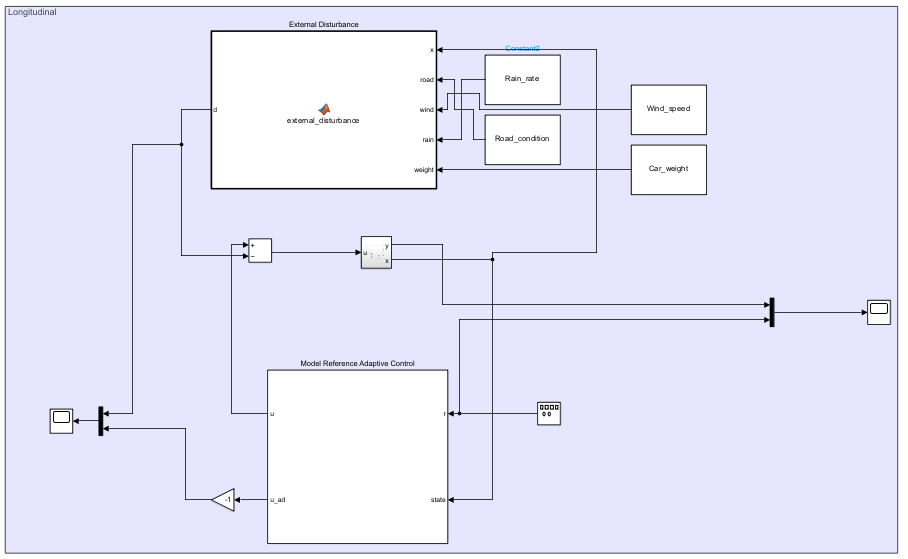

In this model:

- The Longitudinal Model block implements the Longitudinal dynamics nominal model.( Latitudal has the same model but the matrixes are specified for its dynamics)

- The External Disturbance block generates a disturbance to the dynamics.The disturbance is relative to the vehicle conditions.

- The Reference Command block generates reference signal.

- The Model Reference Adaptive Control block outputs the control action  which is an estimate of the disturbance.

*The results are illustrated in the report.*